# Laboratorio 1: Serie de Fourier

[⇦ Información general del análisis de Fourier](matlab: OpenOverview)

1. Considere la serie de seno de Fourier:


$$f(t) = \sum_{n=1}^\infty b_n \sin \left(  2 \pi    t \right)$$


Abra [la aplicación de series de seno y coseno](matlab: SinCosSeries). Establezca la base como seno. Ajuste los coeficientes para determinar los valores de  y  que generan la función que se muestra a continuación. Redondee al medio punto más cercano y guarde su respuesta a continuación. Los otros coeficientes son cero.

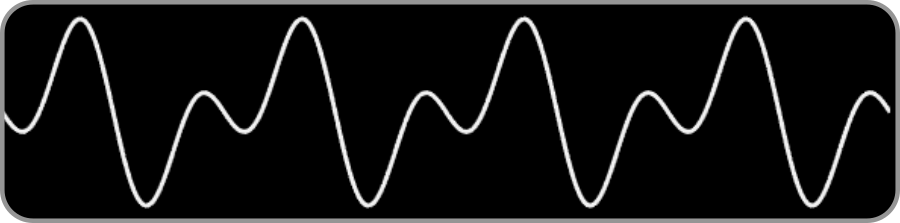

% Reemplace los NaN con sus respuestas
Q1_b2 = NaN;
Q1_b4 = NaN;

2. Considere el coseno desfaseado:


$$g(t) = 1.4\cos(4 \pi t  - \pi/4 )$$


Utilice [la aplicación de magnitud y fase](matlab: run MagnitudePhase.mlapp) para recrear la función usando una serie de Fourier.

a. Utilice la definición de magnitud-fase (panel derecho). ¿Cuáles son los valores de $A_2$ y $\phi_2$ que recrean la función?

Q2_A2 = NaN;
Q2_phi2 = NaN;

b. Utilice la definición de seno-coseno (panel izquierdo). ¿Cuáles son los valores de $a_2$ y $b_2$ que recrean la función? Redondee al décimo más cercano.

Q2_a2 = NaN;
Q2_b2 = NaN;

**Tarea.** Q3-5 usan datos de una señal de audio. Ejecute esta sección para cargar los datos y calcular sus coeficientes de serie de Fourier.

[y,Fs] = audioread("SynthesizedSound.mp4"); % Leer datos
sound(y,Fs) % Reproducir el sonido
plot(y) % Graficar los datos
ylabel("y")
[freq,a,b] = computeFourierCoef(y',Fs); % Calcular coeficientes de serie.

3. Calcule la magnitud y la fase de los coeficientes de Fourier, que se almacenan en los vectores `a` y `b`. Guarde los resultados en `A` y `phi`.

**Pista:** Use [`atan2`](https://www.mathworks.com/help/matlab/ref/atan2.html) para calcular la fase.

A = NaN;
phi = NaN;

4. Grafique el vector de magnitud `A` en contra del vector de frecuencia `freq`, que se da en unidades de Hz. Establezca los límites del eje horizontal en `[0 200]` Hz. Además, etiquete los ejes.

% Escriba su código aquí



5. Hay varios picos distintos en el dominio de la frecuencia. ¿Cuáles son las frecuencias de los picos en Hz?

% Guarde sus respuestas en el vector freqPeaks
% por ejemplo: freqPeaks = [2 5 10]
freqPeaks = NaN;

6. Cree una señal de audio de la forma


$$x(t) = \sum_{n=1}^3 b_n \sin\left(2 \pi f_n t\right)$$


con solo tres términos: las frecuencias de los picos que identificó en la señal de audio en **5**. Establezca el coeficiente de la frecuencia más alta en 0,1 y el coeficiente de las dos frecuencias más bajas en 0,2.

Defina su señal x en términos de la variable `t`. 

t = 0:1/Fs:3; % Utilice esta variable
% Escriba su código aquí



7. Grafique la señal $x$ en contra de $t$. 

8. Reproduzca la señal  como un sonido de audio utilizando la función [`sound`](https://www.mathworks.com/help/matlab/ref/sound.html).

9. Calcule los coeficientes de Fourier de `x` descomentando la línea de abajo. Luego, calcule la magnitud de los coeficientes. Guarde el valor en `Ax`.

% Descomente esta línea de código -->
% [freq,a,b] = computeFourierCoef(x,Fs);

% Escriba su código para calcular la magnitud aquí


10. Grafique el vector de magnitud `A` en contra del vector de frecuencia `freq`, que tiene unidades de Hz. Establezca los límites del eje horizontal en `[0 200]` Hz.

11. Compare la señal original $y$ con la señal $x$ que creó utilizando solo tres frecuencias. 

- ¿Qué similitudes nota entre las dos señales?

- ¿Cuál es la principal diferencia entre ellas?

% Guarde sus respuestas a continuación en las comillas.
similarity = " "
difference = " "

[⇦ Información general del análisis de Fourier](matlab: OpenOverview)

function [freq,a,b] = computeFourierCoef(y,Fs)
% Esta función auxiliar calcula los coeficientes de Fourier
% de una señal y(t) con una frecuencia de muestreo Fs

% FFT
Y = fft(y);

% Coeficientes de serie de Fourier desde FFT
N = numel(y);
Nterms = round(N/2);
YHalf = Y(2:Nterms);
    a0 = real(Y(1))/N;
    a = [a0,2/N*real(YHalf)];
    b = [0,-2/N*imag(YHalf)];

    % Las frecuencias de los coeficientes
    freq = Fs/N*(0:(Nterms-1))';
end

